% OFDM BER Analysis with Different CP Lengths
% This script analyzes the BER performance of an OFDM system under multipath
% channel conditions for various cyclic prefix lengths

% System Parameters (as specified)
M = 16;                    % 16-QAM modulation
Nfft = 64;                 % FFT size
Ng = 0:2:10;              % Guard interval lengths to test
snr = 0:5:30;             % SNR range in dB

% Channel Parameters (as specified)
PowerdB = [0 -8 -17 -21 -25];  % Power profile in dB
Delay = [0 3 5 6 8];          % Delay profile in samples

% Convert power profile from dB to linear scale
PowerLinear = 10.^(PowerdB/10);

% Initialize BER storage matrix
BER = zeros(length(Ng), length(snr));

% Number of OFDM symbols to simulate
numSymbols = 1000;

% Main simulation loop
for ng_idx = 1:length(Ng)
    cp_length = Ng(ng_idx);
    Nsym = Nfft + cp_length;  % Total symbol length including CP
    
    fprintf('Simulating CP length = %d\n', cp_length);
    
    for snr_idx = 1:length(snr)
        fprintf('  SNR = %d dB\n', snr(snr_idx));
        
        total_bits = 0;
        error_bits = 0;
        
        for sym = 1:numSymbols
            % Generate random data bits
            data_bits = randi([0 M-1], Nfft, 1);
            
            % QAM modulation
            X = qammod(data_bits, M, 'UnitAveragePower', true);
            
            % IFFT operation
            x = ifft(X) * sqrt(Nfft);
            
            % Add cyclic prefix
            x_cp = [x(end-cp_length+1:end); x];
            
            % Create multipath channel
            h = zeros(max(Delay) + 1, 1);
            for p = 1:length(Delay)
                h(Delay(p) + 1) = sqrt(PowerLinear(p)) * (randn + 1j*randn)/sqrt(2);
            end
            
            % Pass through channel
            y_channel = conv(x_cp, h);
            y_channel = y_channel(1:Nsym);  % Keep only symbol duration
            
            % Add white Gaussian noise
            signal_power = mean(abs(y_channel).^2);
            noise_power = signal_power / (10^(snr(snr_idx)/10));
            noise = sqrt(noise_power/2) * (randn(size(y_channel)) + 1j*randn(size(y_channel)));
            y = y_channel + noise;
            
            % Remove CP
            y_nocp = y(cp_length+1:end);
            
            % FFT operation
            Y = fft(y_nocp) / sqrt(Nfft);
            
            % Channel estimation (assuming perfect channel knowledge)
            H = fft([h; zeros(Nfft-length(h), 1)]);
            
            % Equalization
            Y_eq = Y ./ H;
            
            % QAM demodulation
            data_received = qamdemod(Y_eq, M, 'UnitAveragePower', true);
            
            % Count bit errors
            bit_errors = sum(sum(de2bi(data_bits,log2(M)) ~= de2bi(data_received,log2(M))));
            total_bits = total_bits + Nfft * log2(M);
            error_bits = error_bits + bit_errors;
        end
        
        % Calculate BER for current configuration
        BER(ng_idx, snr_idx) = error_bits / total_bits;
    end
end

Simulating CP length = 0


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 2


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 4


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 6


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 8


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


Simulating CP length = 10


  SNR = 0 dB
  SNR = 5 dB
  SNR = 10 dB
  SNR = 15 dB
  SNR = 20 dB
  SNR = 25 dB
  SNR = 30 dB


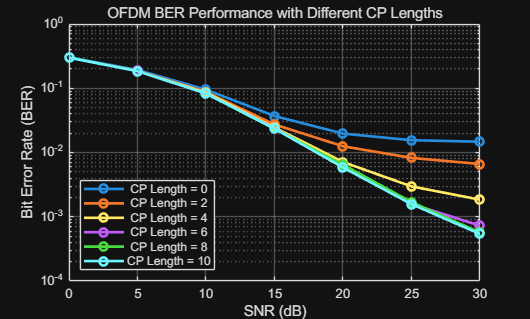


% Plot results
figure;
semilogy(snr, BER, 'LineWidth', 2, 'Marker', 'o');
grid on;
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('OFDM BER Performance with Different CP Lengths');
legend(cellstr(num2str(Ng', 'CP Length = %d')), 'Location', 'southwest');
ylim([1e-4 1]);